# LAB 3 - Trevor Callow - MAT 275

# Exercise 1

#### **Read the instructions in your lab pdf file carefully!**

### **Part (a)**

***NOTE****: We often define the right-hand side of an ODE as some function, say *$f$*, in terms of the input and output variables in the ODE. For example, *$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\right)=3\ldotp 25y\ldotp$* Although the ODE does not explicitly depend on *$t$*, it does so implicitly, since *$y$* is a function of *$t$*. Therefore, *$t$* is an input variable of *$f$*.* 

Define ODE function $f$for your version of the lab.

f=@(t, y) .5*y;

Define vector $t$ of time-values over the interval in your version of the lab, to compute analytical solution vector.

t=linspace(0,2.5,100);

Create vector of analytical solution values at corresponding t values.

y = 3*exp(0.5 * t);

***NOTE:**** In your version of the lab you were given a table in problem1(a), which you need to fill out. This table has four different values of N - call them Nsmall, Nmed, Nlarge and Nhuge (where, of course, Nsmall < Nmed < Nlarge < Nhuge). For the following steps, please use notation consistent with the protocol and appropriate for your version of the lab.  For example, if in your version *`Nsmall=5`* timesteps, then use the variable name *`t5`* to represent the vector of t-points in the solution with number of steps N=5. Also, if in your version *`Nlarge=500`* timesteps, use variable name *`y500`  t*o represent the numerical solution vector produced from Euler's method, and use the name *`e500`* to denote the corresponding error. In the following comments, I refer to "Euler's method" as "forward Euler's method," which is more precise since there is also a backward Euler's method. I use "IVP" as an abbreviation for Initial Value Problem, which for our purposes here means an ODE with associated initial condition. Delete this note upon submission.*

Solve IVP numerically using forward Euler's method with Nsmall timesteps (use variable names as instructed).

Nsmall = 5

Nsmall = 5

[~ , y5]=euler(f,[0,2.5],3,Nsmall);

Solve IVP numerically using forward Euler's method with Nmed timesteps (use variable names as instructed).

Solve IVP numerically using forward Euler's method with Nlarge timesteps (use variable names as instructed).

Nmed = 50

Nmed = 50

Solve IVP numerically using forward Euler's method with Nhuge timesteps (use variable names as instructed).

[ t50 ,  y50 ]= euler(f,[0,2.5],3,Nmed);

In the following steps, we define error as exact - numerical solution value at the last time step

Nlarge=500

Nlarge = 500

Compute numerical solution error at the last time step for forward Euler with Nsmall timesteps (use variable names as instructed).

[ t500 , y500 ]=euler(f,[0,2.5],3,Nlarge);

Compute numerical solution error at the last time step for forward Euler with Nmed timesteps (use variable names as instructed).

Nhuge=5000

Nhuge = 5000

Compute numerical solution error at the last time step for forward Euler with Nlarge timesteps (use variable names as instructed).

[ t5000 , y5000 ]= euler (f,[0,2.5],3,Nhuge);

Compute numerical solution error at the last time step for forward Euler with Nhuge timesteps (use variable names as instructed).

e5=(y(end)-y5(end))

e5 = 1.3158

e50=(y(end)-y50(end))

e50 = 0.1597

e500=(y(end)-y500(end))

e500 = 0.0163

e5000=(y(end)-y5000(end))

e5000 = 0.0016

Compute ratio of errors between N=Nsmall and N=Nmed. 

ratio1=(e5/e50)

ratio1 = 8.2388

Compute ratio of errors between N=Nmed and N=Nlarge.

ratio2=(e50/e500)

ratio2 = 9.7851

Compute ratio of errors between N=Nlarge and N=Nhuge. 

ratio3=(e500/e5000)

ratio3 = 9.9780

***NOTE: ****To complete the following table, simply run this section after you've finished the steps above and copy and paste your errors and ratios into the code below.  Delete this note upon submission.*

### **FILL OUT THE TABLE BELOW **

Display the table of errors and ratios of consecutive errors for the  numerical solution at `t=tfina`l (the last element in the solution vector).  **REPLACE** words "Nsmall", "Nmed", "Nlarge" and "Nhuge","Nsmall", "yNmed", "yNlarge" and "yNhuge" , "eNsmall",..."ratio1", ... by the appropriate numbers of steps you were given in your version of the lab and by the appropriate values you computed above.  Also, note that in your version of the lab you already have some values entered in the table, to help you check your code is correct. You need to fill out all the cells in the table!

N ={Nsmall;Nmed;Nlarge;Nhuge};
Approximation={y5(end);y50(end);y500(end);y5000(end)};
error={e5;e50;e500;e5000};
ratio ={'N/A'; ratio1;ratio2;ratio3};
table(N,Approximation,error,ratio)

ans = 4×4 table
       N        Approximation      error         ratio   
    ________    _____________    __________    __________

    {[   5]}     {[ 9.1553]}     {[1.3158]}    {'N/A'   }
    {[  50]}     {[10.3113]}     {[0.1597]}    {[8.2388]}
    {[ 500]}     {[10.4547]}     {[0.0163]}    {[9.7851]}
    {[5000]}     {[10.4694]}     {[0.0016]}    {[9.9780]}


### **Part (b)**

**The amount of errror relates to the amount of steps this code is taking. when the number increases the amount of error decreases. this confirms eulers method**

### **Part (c)**

**This is an Overestimation because of the concavity of the function. Concave down would hav tangent at the top and concave up would have tangent at the bottom**

# Exercise 2

**Read the instructions in your lab pdf file carefully!**

### Part (a)

Plot slopefield for the new ODE  using the given commands. 

t = 0:0.3:4;
y = -8:1.8:10;
[T,Y]=meshgrid(t,y);
dT=ones(size(T));
dY=-4.4*Y;
quiver (T,Y,dT,dY)
axis tight
hold on

### Part (b)

Define vector t of time-values over the  given interval  to define analytical solution vector.

t = linspace(0,4,100);

Create vector of analytical solution values at corresponding t values.

y=3*exp(-4.4*t)

y =     3.0000    2.5114    2.1024    1.7599    1.4733    1.2333    1.0325    0.8643    0.7235    0.6057    0.5070    0.4245    0.3553    0.2975    0.2490    0.2085    0.1745    0.1461    0.1223    0.1024    0.0857    0.0717    0.0601    0.0503    0.0421    0.0352    0.0295    0.0247    0.0207    0.0173    0.0145    0.0121    0.0102    0.0085    0.0071    0.0060    0.0050    0.0042    0.0035    0.0029    0.0024    0.0020    0.0017    0.0014    0.0012    0.0010    0.0008    0.0007    0.0006    0.0005


**NOTE**: *The "hold on" command in the segment of code to plot the slope field indicates to MATLAB to add future plots to the same window unless otherwise specified using the "hold off" command.*

Plot analytical solution vector with slopefield from (a). 

plot(t,y,"linewidth",2)

### Part (c)

***NOTE:**** Recall we can define the right-hand side of an ODE as some function *$f$* . In the case of a one-dimensional autonomous ODE, we may define *$f$*such that *$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\right)$

Define ODE function.

f=@(t,y)-4.4*y

f = function_handle with value:
    @(t,y)-4.4*y


Compute numerical solution to IVP with N timesteps using forward Euler.

[ t , y ] = euler (f,[0,4],3,5);

Plot numerical solution with analytical solution from (b) and slopefield from (a) using circles to distinguish between the approximated data (i.e., the numerical solution values) and actual (analytical) solution.

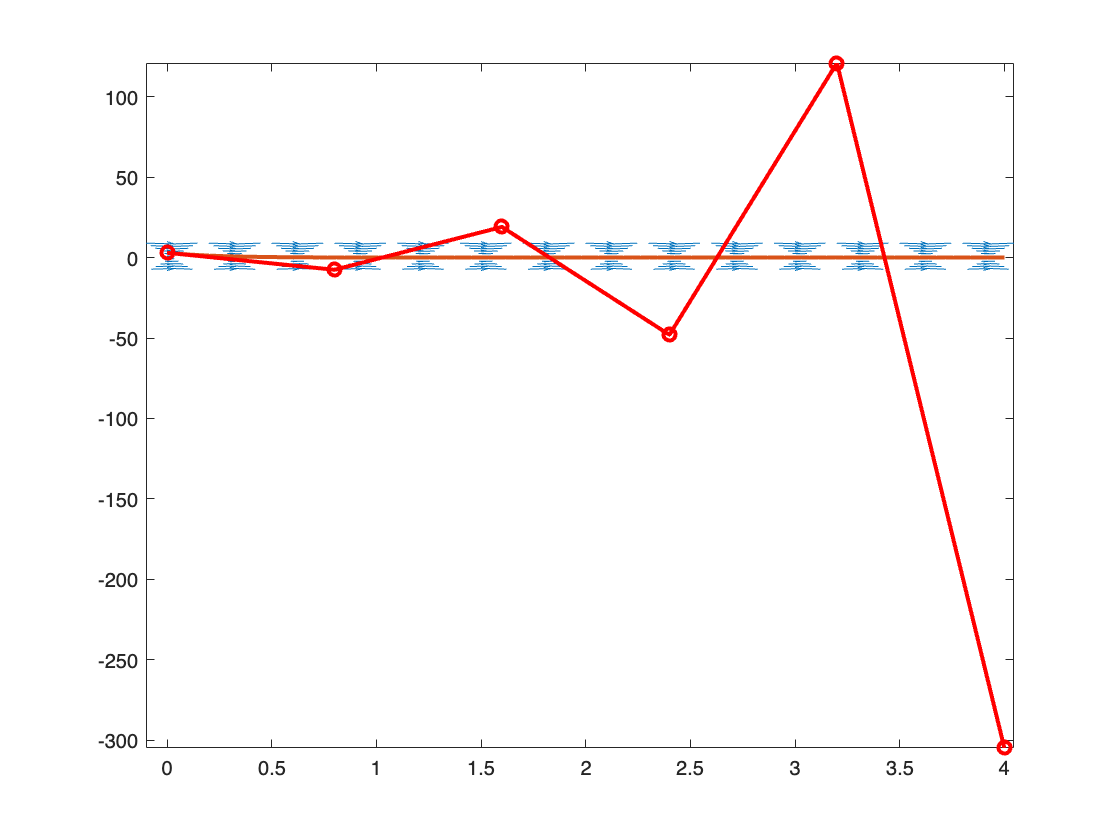

plot(t,y,"ro-","LineWidth",2)
hold off;   %end plotting in this figure window

** Your response to the essay question for part (c) goes here. **

*Please do not  answer the question with "the numerical solution is inaccurate because  the stepsize is too big" or "because there are not enough points in the numerical solution." What is it about this particular solution that makes forward Euler so inaccurate for this stepsize? Think about *it.

### Part (d)

 Define new grid of t and y values at which to plot vectors for slope field.

figure
t=0:.3:4;
y= -1.2:.04:2.6;


Plot slope field  corresponding to the new grid.

[T , Y] = meshgrid (t,y);
dT = ones(size(T));
dY = -4.4*Y;
quiver (T, Y, dT, dY)
axis tight
hold on

Define vector t of time-values over the given interval to define analytical soution vector.

t = linspace(0,4,100);

Create vector of analytical solution values at corresponding t values.

y = 3*exp(-4.4*t);

Define ODE function.

f=@(t,y)-4.4*t

f = function_handle with value:
    @(t,y)-4.4*t


Compute numerical solution to IVP with the given timesteps using forward Euler. 

[ t , y ]= euler(f,[0,4],3,5)

t =          0
    0.8000
    1.6000
    2.4000
    3.2000
    4.0000


y =     3.0000
    3.0000
    0.1840
   -5.4480
  -13.8960
  -25.1600


plot numerical solution together with slope field and analytical solution

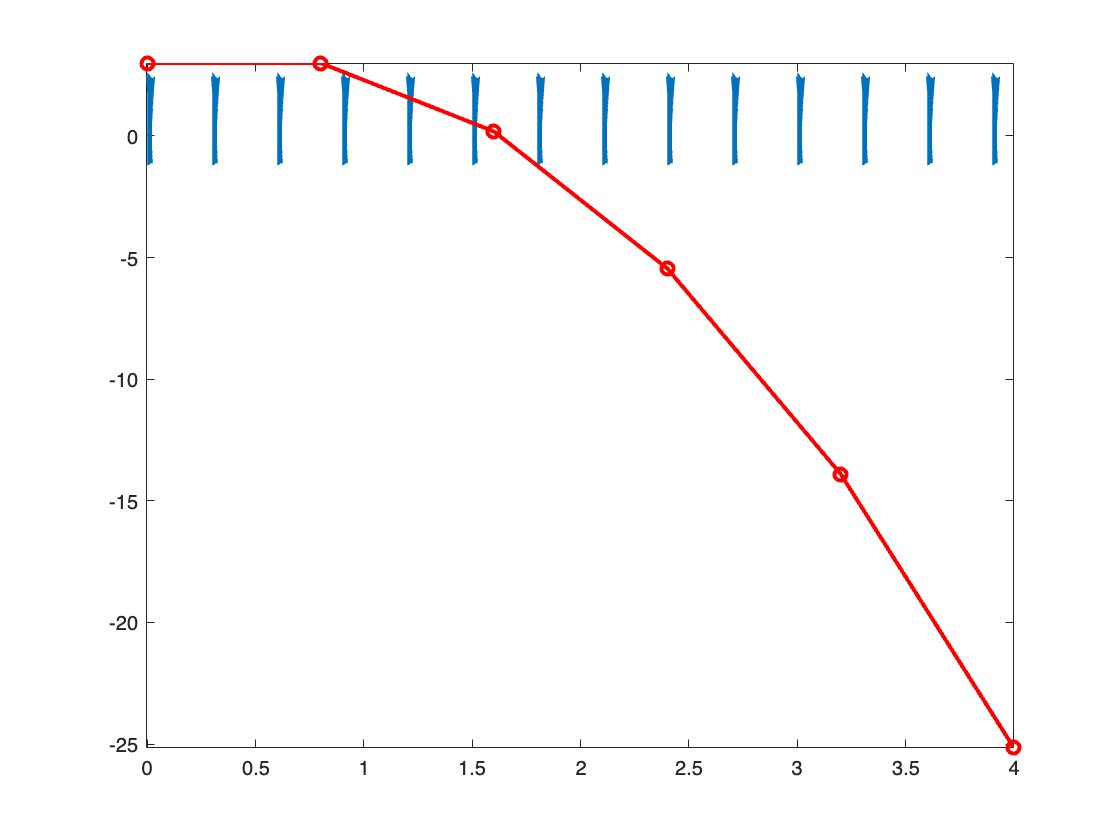

plot(t,y,"ro-","LineWidth",2)
hold off

**The inaccuraces went down leading to a more normal looking curve then the previous.**

# Exercise 3

**Read the instructions in your lab pdf file carefully!**

Display contents of impeuler M-file.

type 'impeuler.m'

 function [t,y] = euler(f,tspan,y0,N)

% Solves the IVP y' = f(t,y), y(t0) = y0 in the time interval tspan = [t0,tf]
% using Euler's method with N time steps.
%  Input:
%  f = name of inline function or function M-file that evaluates the ODE
%          (if not an inline function,  use: euler(@f,tspan,y0,N))
%          For a system, the f must be given as column vector.
%  tspan = [t0, tf] where t0 = initial time value and tf = final time value
%  y0  = initial value of the dependent variable. If solving a system,
%           initial conditions must be given as a vector.
%  N   = number of steps used.
% Output:
%  t = vector of time values where the solution was computed
%  y = vector of computed solution values.

m = length(y0);
t0 = tspan(1);
tf = tspan(2);
h = (tf-t0)/N;             % evaluate the time step size
t = linspace(t0,tf,N+1);    % create the vector of t values
y = zeros(m,N+1);   % allocate memory for the output y
y(:,1) = y0';              % set initial condition
for n=1:

Define ODE function. 

f=@(t,y).5*y

f = function_handle with value:
    @(t,y).5*y


Compute numerical solution to IVP with Nsmall timesteps using "improved Euler."

t = linspace(0,2.5,100);
[ t5 , y5 ] = impeuler(f,[0,2.5], -1, 5)

t5 =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000


y5 =    -1.0000
   -1.2500
   -1.5625
   -1.9531
   -2.4414
   -3.0518


*How does your output compare to that in the protocol? They should be the same.*

# Exercise 4

**Read the instructions in your lab pdf file carefully!**

***NOTE: Here, we repeat all the steps from parts (a) and (b) in exercise 1, but we use "improved Euler" instead of forward Euler (or regular Euler). Make sure to document your code appropriately.***

### **Part (a)**

Define ODE function $f$for your version of the lab.

f=@(t,y).5*y

f = function_handle with value:
    @(t,y).5*y


Define vector $t$ of time-values over the interval in your version of the lab, to compute analytical solution vector.

t = linspace(0,2.5,100);

Create vector of analytical solution values at corresponding t values.

y = 3* exp(.5*t)

y =     3.0000    3.0381    3.0767    3.1158    3.1554    3.1955    3.2361    3.2772    3.3189    3.3610    3.4037    3.4470    3.4908    3.5351    3.5801    3.6256    3.6716    3.7183    3.7655    3.8134    3.8618    3.9109    3.9606    4.0109    4.0619    4.1135    4.1657    4.2187    4.2723    4.3266    4.3815    4.4372    4.4936    4.5507    4.6085    4.6671    4.7264    4.7864    4.8472    4.9088    4.9712    5.0344    5.0983    5.1631    5.2287    5.2952    5.3624    5.4306    5.4996    5.5695


Solve IVP numerically using improved Euler's method with Nsmall timesteps (use variable names as instructed).

[ t5, y5 ]= impeuler(f,[0,2.5],3,Nsmall);

Solve IVP numerically using improved Euler's method with Nmed timesteps (use variable names as instructed).

[ t50 , y50 ]= impeuler(f,[0,2.5],3, Nmed);

Solve IVP numerically using improved Euler's method with Nlarge timesteps (use variable names as instructed).

[ t500 , y500 ]= impeuler(f,[0,2.5],3,Nlarge);

Solve IVP numerically using improved Euler's method with Nhuge timesteps (use variable names as instructed).

[ t5000, y5000 ]= impeuler(f,[0,2.5],3,Nhuge);

In the following steps, we define error as exact - numerical solution value at the last time step

Compute numerical solution error at the last time step for improved Euler with Nsmall timesteps (use variable names as instructed).

es = (y(end)-y5(end))

es = 1.3158

Compute numerical solution error at the last time step for improved Euler with Nmed timesteps (use variable names as instructed).

e50 = (y(end)-y50(end))

e50 = 0.1597

Compute numerical solution error at the last time step for improved Euler with Nlarge timesteps (use variable names as instructed).

e500 = (y(end)-y500(end))

e500 = 0.0163

Compute numerical solution error at the last time step for improved Euler with Nhuge timesteps (use variable names as instructed).

e5000 = (y(end)-y5000(end))

e5000 = 0.0016

Compute ratio of errors between N=Nsmall and N=Nmed. 

r1 = (e5/e50)

r1 = 8.2388

Compute ratio of errors between N=Nmed and N=Nlarge.

r2 = (e50/e500)

r2 = 9.7851

Compute ratio of errors between N=Nlarge and N=Nhuge. 

r3 = (e500/e5000)

r3 = 9.9780

### **FILL OUT THE TABLE BELOW **

Display the table of errors and ratios of consecutive errors for the  numerical solution at `t=tfina`l (the last element in the solution vector).  **REPLACE** words "Nsmall", "Nmed", "Nlarge" and "Nhuge","Nsmall", "yNmed", "yNlarge" and "yNhuge" , "eNsmall",..."ratio1", ... by the appropriate numbers of steps you were given in your version of the lab and by the appropriate values you computed above.  

N ={Nsmall;Nmed;Nlarge;Nhuge};
Approximation={y5(end);y50(end);y500(end);y5000(end)};
error={es;e50;e500;e5000};
ratio ={'N/A'; r1 ; r2 ; r3};
table(N,Approximation,error,ratio)

ans = 4×4 table
       N        Approximation      error         ratio   
    ________    _____________    __________    __________

    {[   5]}     {[ 9.1553]}     {[1.3158]}    {'N/A'   }
    {[  50]}     {[10.3113]}     {[0.1597]}    {[8.2388]}
    {[ 500]}     {[10.4547]}     {[0.0163]}    {[9.7851]}
    {[5000]}     {[10.4694]}     {[0.0016]}    {[9.9780]}


### **Part (b)**

**The ratios are a lot more similar to eachother allowing for this to show improvemnt. Error is also a lot less then the previous table.**

# Exercise 5

**Read the instructions in your lab pdf file carefully!**

***NOTE****: Here, we repeat all the steps from exercise 2, except using improved Euler rather than forward Euler. Remember code doc. *

### Part (a)

Plot slopefield for the new ODE  using the given commands. 

t = 0:.3:4;
y = -8:1.8:10;
[ T , Y ] = meshgrid(t,y)

T =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000
         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000
         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000
         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000
         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000
         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000
         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000
         

Y =    -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000
   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000   -6.2000
   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000
   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000   -2.6000
   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000   -0.8000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000    2.8000
    4.600

dT = ones(size(T));
dY = -4.4*Y

dY =    35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000   35.2000
   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800   27.2800
   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600
   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400   11.4400
    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200    3.5200
   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000   -4.4000
  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200  -12.3200
  -20.24

quiver(T,Y,dT,dY)
axis tight
hold on

### Part (b)

Define vector t of time-values over the  given interval  to define analytical solution vector.

t = linspace(0,4,100);

Create vector of analytical solution values at corresponding t values.

y = 3*exp(-4.4*t);

Plot analytical solution vector with slopefield from (a). 

plot(t,y,"Linewidth",2)

### Part (c)

Define ODE function.

f=@(t,y)-4.4*y

f = function_handle with value:
    @(t,y)-4.4*y


Compute numerical solution to IVP with N timesteps using improved Euler.

[ T , Y]= impeuler(f,[0,4],3,5)

T =          0
    0.8000
    1.6000
    2.4000
    3.2000
    4.0000


Y =     3.0000
   -7.5600
   19.0512
  -48.0090
  120.9827
 -304.8765


Plot numerical solution with analytical solution from (b) and slopefield from (a) using circles to distinguish between the approximated data (i.e., the numerical solution values) and actual (analytical) solution.

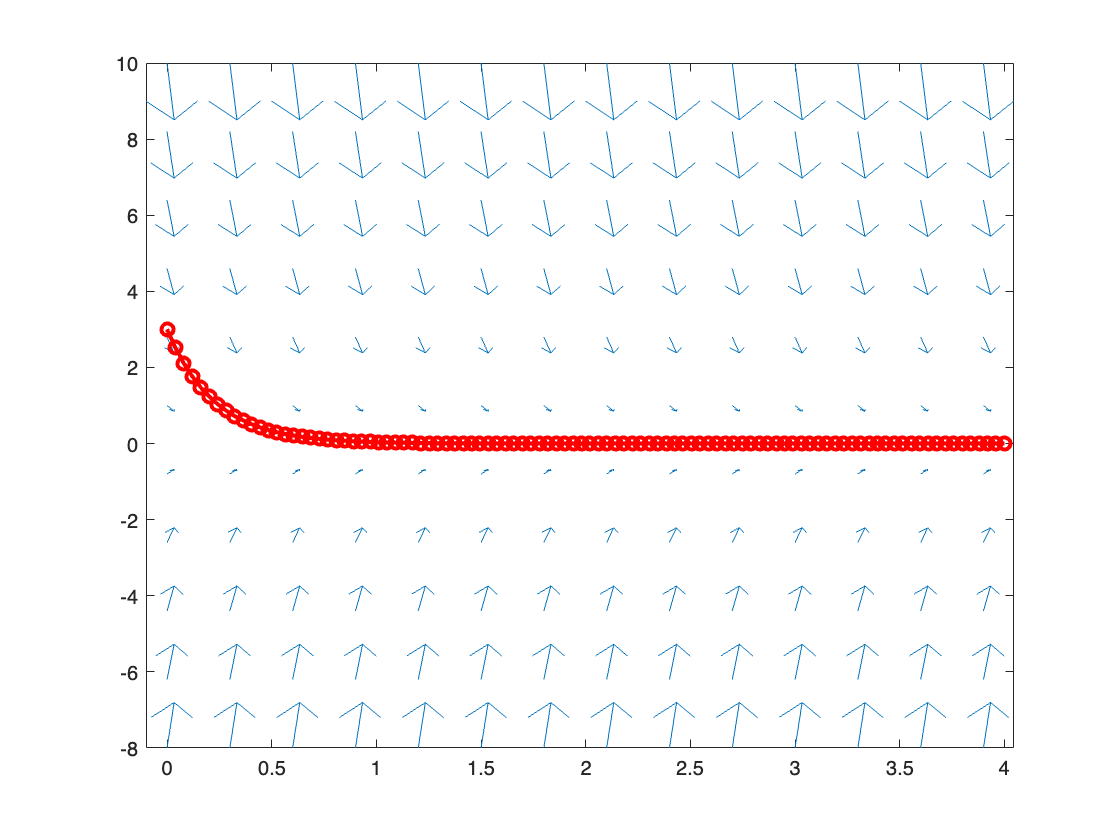

plot(t,y,"ro-","LineWidth",2)

hold off;   %end plotting in this figure window

** The approximations are a lot more accurate and make more since then the previous but these still have a small error procent by is closer to eulers.**

### Part (d)

 Define new grid of t and y values at which to plot vectors for slope field.

figure
t=0:.3:4;
y= -1.2:.04:2.6;

Plot slope field  corresponding to the new grid.

[T , Y] = meshgrid (t,y);
dT = ones(size(T));
dY = -4.4*Y;
quiver (T, Y, dT, dY)
axis tight
hold on

Define vector t of time-values over the given interval to define analytical soution vector.

t = linspace(0,4,100);

Create vector of analytical solution values at corresponding t values.

y = 3*exp(-4.4*t);

Define ODE function.

f=@(t,y)-4.4*t

f = function_handle with value:
    @(t,y)-4.4*t


Compute numerical solution to IVP with the given timesteps using improved Euler. 

[ t , y ]= impeuler(f,[0,4],3,5)

t =          0
    0.8000
    1.6000
    2.4000
    3.2000
    4.0000


y =     3.0000
    3.0000
    0.1840
   -5.4480
  -13.8960
  -25.1600


Plot numerical solution together with slope field and analytical solution

plot(t,y,"ro-","LineWidth",2)
hold off

**The incosistencies have decreased while decreasing the size of each point. The drops are gone isntead of having the eul;er method drops and it is an average of slopes.**